Initialization

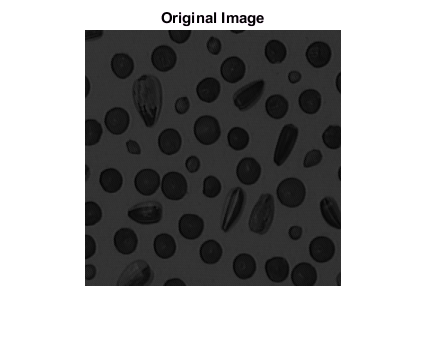

clear all; close all; clc;
X = imread('Blood2.bmp'); I = im2single(X); % Read Image and convert to float (0-1)
figure(); imshow(I); title('Original Image');

Image Statistics

Imin = min(I(:));
Imax = max(I(:));
Imea = mean(I(:));
Istd = std(I(:));
Ivar = var(I(:));
fprintf ('\nMinimum   : %f', Imin);


Minimum   : 0.015686

fprintf ('\nMaximum   : %f', Imax);


Maximum   : 0.235294

fprintf ('\nMittelwert: %f', Imea);


Mittelwert: 0.157782

fprintf ('\nStd.abw   : %f', Istd);


Std.abw   : 0.055778

fprintf ('\nVarianz   : %f', Ivar);


Varianz   : 0.003111

Histogram

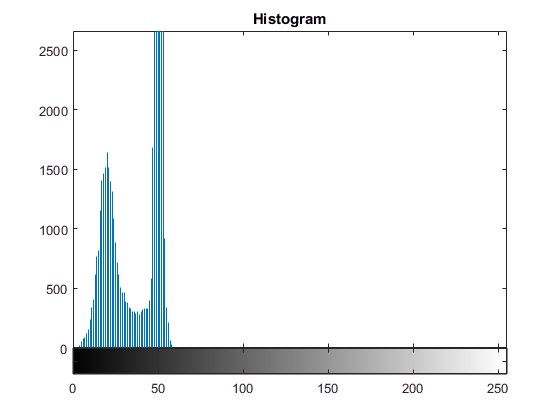

[B,~] = gray2ind (I,256);         % Float grayscale to 8 bit int
figure(); imhist(B); title('Histogram');

Cumulative Histogram

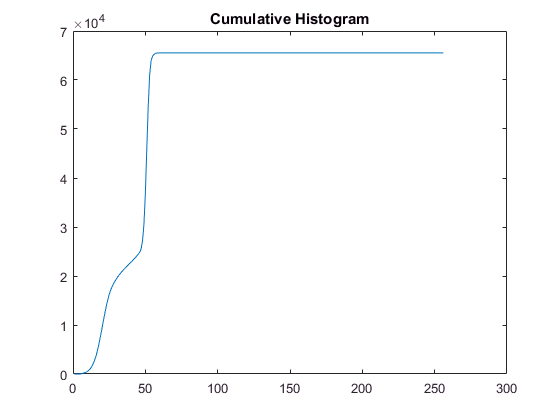

cumHist = cumsum(imhist(B));
figure(); plot(cumHist); title('Cumulative Histogram');

Histrogram Equalization


fprintf('\nHistogram Equalization')


Histogram Equalization

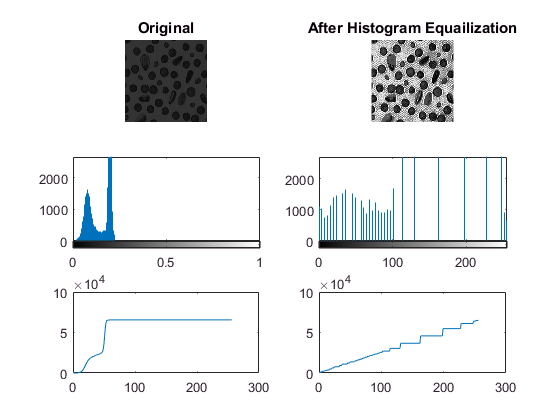

figure();
subplot(3,2,1); imshow(I); title('Original');
subplot(3,2,3); imhist(I);
[B,~] = gray2ind(I,256);
cumHist = cumsum(imhist(B));
subplot(3,2,5); plot(cumHist);

I2 = histeq(I);
subplot(3,2,2); imshow(I2); title('After Histogram Equailization');
[B,~] = gray2ind(I2,256);
subplot(3,2,4); imhist(B);
cumHist = cumsum(imhist(B));
subplot(3,2,6); plot(cumHist);

Image Adjustments - Contrast

fprintf('\nImage Adjustments - Contrast')


Image Adjustments - Contrast

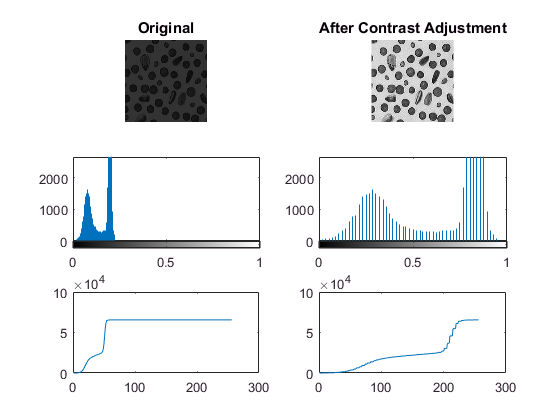

figure();
subplot(3,2,1); imshow(I); title('Original');
subplot(3,2,3); imhist(I);
[B,~] = gray2ind(I,256);
cumHist = cumsum(imhist(B));
subplot(3,2,5); plot(cumHist);

I2 = imadjust(I,[Imin Imax],[0 1]);
subplot(3,2,2); imshow(I2); title('After Contrast Adjustment');
[B,~] = gray2ind(I2,256);
subplot(3,2,4); imhist(I2);
cumHist = cumsum(imhist(B));
subplot(3,2,6); plot(cumHist);

Image Adjustments - Gamma Correction

fprintf('\nImage Adjustments - Gamma Correction')


Image Adjustments - Gamma Correction

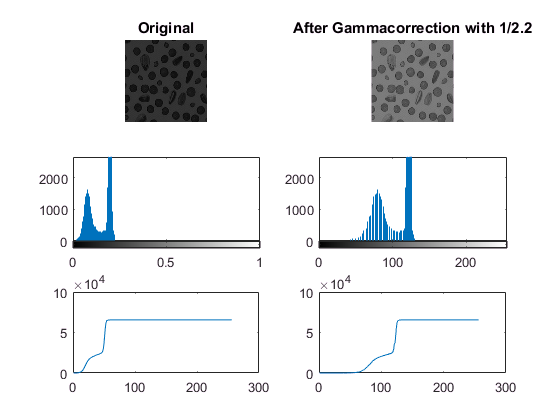

figure();
subplot(3,2,1); imshow(I); title('Original');
subplot(3,2,3); imhist(I);
[B,~] = gray2ind(I,256);
cumHist = cumsum(imhist(B));
subplot(3,2,5); plot(cumHist);

GammaValue = 1.0/2.2;
%I2 = 255 * (I/255).^ GammaValue;   % Gamma correction for 8 bit int
I2 = I.^ GammaValue;                % Gamma correction for float (0-1)
subplot(3,2,2); imshow(I2); title('After Gammacorrection with 1/2.2');
[B,~] = gray2ind(I2,256);
subplot(3,2,4); imhist(B);
cumHist = cumsum(imhist(B));
subplot(3,2,6); plot(cumHist);

Image Adjustments - Linear Brightness Correction

fprintf('\nLinear Brightness Correction')


Linear Brightness Correction

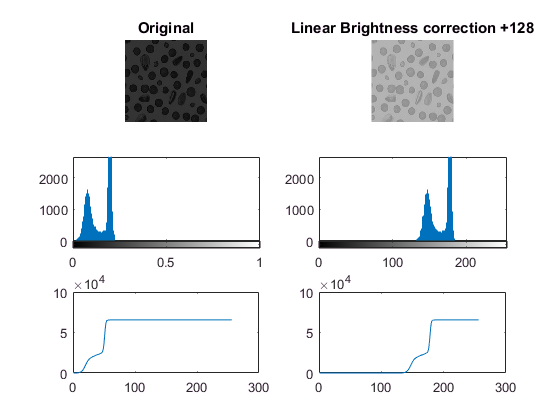

figure();
subplot(3,2,1); imshow(I); title('Original');
subplot(3,2,3); imhist(I);
[B,~] = gray2ind(I,256);
cumHist = cumsum(imhist(B));
subplot(3,2,5); plot(cumHist);

I2 = imadjust(I,[Imin Imax],[Imin+0.5 Imax+0.5]);
subplot(3,2,2); imshow(I2); title('Linear Brightness correction +128');
[B,~] = gray2ind(I2,256);
subplot(3,2,4); imhist(B);
cumHist = cumsum(imhist(B));
subplot(3,2,6); plot(cumHist);

Binarisierung

fprintf('\nBinarization\n')


Binarization


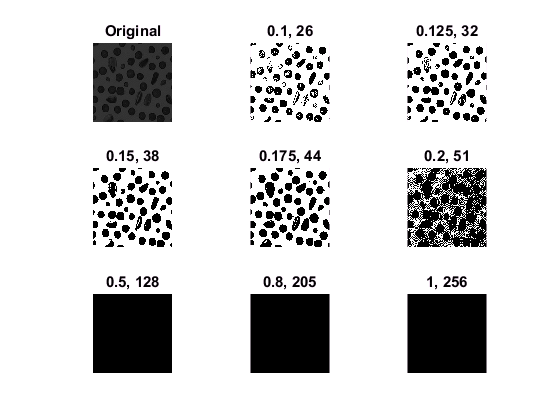

figure();
subplot(3,3,1); imshow(I); title('Original');

subplot(3,3,2); imshow(im2bw(I,0.1)); title('0.1, 26');
subplot(3,3,3); imshow(im2bw(I,0.125)); title('0.125, 32');
subplot(3,3,4); imshow(im2bw(I,0.15)); title('0.15, 38');
subplot(3,3,5); imshow(im2bw(I,0.175)); title('0.175, 44');
subplot(3,3,6); imshow(im2bw(I,0.2)); title('0.2, 51');
subplot(3,3,7); imshow(im2bw(I,0.5)); title('0.5, 128');
subplot(3,3,8); imshow(im2bw(I,0.8)); title('0.8, 205');
subplot(3,3,9); imshow(im2bw(I,1)); title('1, 256');